clear;
clc;

set( groot, 'defaultLineLineWidth', 1.2 ) ; % plot line 두께 지정
set( groot, 'defaultAxesXGrid', 'on' ) ; % x축 방향으로 grid 생성
set( groot, 'defaultAxesYGrid', 'on' ) ; % y축 방향으로 grid 생성
set( groot, 'defaultAxesTitleFontSizeMultiplier', 1.5);  % Title 크기 설정
set( groot, 'defaultAxesFontSize', 12 ); % 축에 있는 글씨 크기 지정
set( groot, 'defaultAxesFontName', 'Times New Roman'); % 축에 있는 글씨 폰트 지정
set( groot, 'defaultFigureColor', 'w'); % figure 색상

% Load data
dateStr = '20250901';      % log date
runIdx  = '1';             % log nums

scriptFullPath = matlab.desktop.editor.getActiveFilename;
currentDir = fileparts(scriptFullPath);

while true
    [parentDir, folderName] = fileparts(currentDir);
    if strcmp(folderName, 'mppi_solver')
        projectRoot = currentDir;
        break;
    end
    if isempty(parentDir)
        error('Directory mppi_solver not found');
    end
    currentDir = parentDir;
end

absPath = fullfile(projectRoot, 'runs', ...
                   dateStr, runIdx, 'mppi_canadarm');

joint_angle = h5read(fullfile(absPath, 'mppi_canadarm.mat'), '/joint_angle');
joint_angular_velocity = h5read(fullfile(absPath, 'mppi_canadarm.mat'), '/joint_angular_velocity' );

clearvars dateStr runIdx scriptFullPath currentDir parentDir folderName projectRoot absPath

init_data_idx = 1;
end_data_idx = init_data_idx+2000;
joint_angle = joint_angle(:,init_data_idx:end_data_idx);
joint_angular_velocity = joint_angular_velocity(:,init_data_idx:end_data_idx);

joint_angle(1,:) = joint_angle(1,:) - joint_angle(1,1);
joint_angular_velocity(1,:) = joint_angular_velocity(1,:) - joint_angular_velocity(1,1);

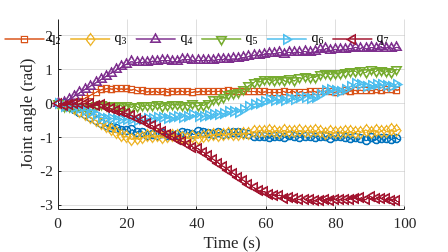

joint_angle_sim_time = joint_angle(1,:);
joint_angle_plot = joint_angle(2:8,:);

f = figure('Units','pixels','WindowStyle','normal');
f.OuterPosition = [100 100 800 450];
markers = {'o','s','d','^','v','>','<'};
hold on
h = plot(joint_angle_sim_time, joint_angle_plot);
for k = 1:numel(h)
    h(k).Marker = markers{k};
    h(k).MarkerIndices = 1:30:length(joint_angle_sim_time);
end
hold off
grid off
xlabel("Time (s)")
ylabel("Joint angle (rad)")
ylim([-3.14 2.5])
grid on
legend("q_1","q_2","q_3","q_4","q_5","q_6","q_7", ...
    'Location','north', ...
    'Orientation','horizontal', ...
    'Box','off')

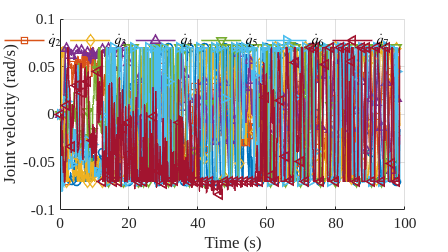

joint_angular_velocity_sim_time = joint_angular_velocity(1,:);
joint_angular_velocity_plot = joint_angular_velocity(2:8,:);

f = figure('Units','pixels','WindowStyle','normal');
f.OuterPosition = [100 100 800 450];
hold on
h2 = plot(joint_angular_velocity_sim_time, joint_angular_velocity_plot);
for k = 1:numel(h)
    h2(k).Marker = markers{k};
    h2(k).MarkerIndices = 1:30:length(joint_angular_velocity_sim_time);
end
hold off
grid off
xlabel("Time (s)")
ylabel("Joint velocity (rad/s)")
grid on
legend("$\dot{q}_1$","$\dot{q}_2$","$\dot{q}_3$","$\dot{q}_4$","$\dot{q}_5$","$\dot{q}_6$","$\dot{q}_7$",...
    'Interpreter','latex', ...
    'Location','north', ...
    'Orientation','horizontal', ...
    'Box','off')

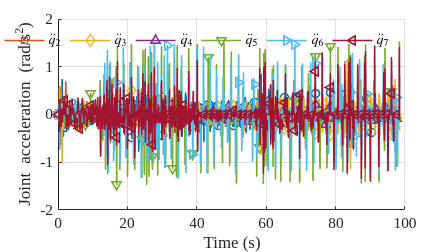

joint_angular_acceleration_plot = accel_from_qv(joint_angle_plot, joint_angular_velocity_plot, joint_angular_velocity_sim_time);

f = figure('Units','pixels','WindowStyle','normal');
f.OuterPosition = [100 100 800 450];
hold on
h3 = plot(joint_angular_velocity_sim_time, joint_angular_acceleration_plot);
for k = 1:numel(h)
    h3(k).Marker = markers{k};
    h3(k).MarkerIndices = 1:30:length(joint_angular_velocity_sim_time);
end
hold off
grid off
xlabel("Time (s)")
ylabel("Joint acceleration (rad/s^2)")
grid on
legend("$\ddot{q}_1$","$\ddot{q}_2$","$\ddot{q}_3$","$\ddot{q}_4$","$\ddot{q}_5$","$\ddot{q}_6$","$\ddot{q}_7$",...
    'Interpreter','latex', ...
    'Location','north', ...
    'Orientation','horizontal', ...
    'Box','off')

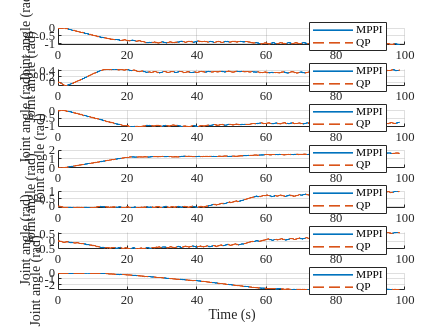

% if QP

QP_time = joint_angle_sim_time;
Q_joint_angle_plot = joint_angle_plot;

f = figure('Units','pixels','WindowStyle','normal');
f.OuterPosition = [100 100 800 1000];

for i = 1:7
    subplot(7,1,i); hold on
    plot(joint_angle_sim_time, joint_angle_plot(i,:), '-','DisplayName','MPPI');
    plot(QP_time, Q_joint_angle_plot(i,:), '--','DisplayName','QP');
    
    ylabel("Joint angle (rad)")
    if i == 7
       xlabel("Time (s)")
    end
    grid on
    legend('Location','best')
    hold off
end

function a = accel_from_qv(q, v, t)
    [nq, N] = size(q);
    [nv, Nv] = size(v);

    a = zeros(size(v), 'like', v);
    t = t(:).';

    for k = 2:N-1
        h1 = t(k)   - t(k-1);
        h2 = t(k+1) - t(k);
        a(:,k) = (-h2/(h1*(h1+h2))) * v(:,k-1) ...
               + ((h2-h1)/(h1*h2))  * v(:,k)   ...
               + (h1/(h2*(h1+h2)))  * v(:,k+1);
    end
    a(:,1) = (v(:,2) - v(:,1))       / (t(2)-t(1));
    a(:,N) = (v(:,N) - v(:,N-1))     / (t(N)-t(N-1));
end